% AAE564 HW5 Problem9 MATLAB Script
% Tomoki Koike
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% (a)

% L8
% linear
global m l g ye t1e t2e
define_params("L8");
xe = trim('db_pend_cart_lin');
[A, B, C, D] = linmod('db_pend_cart_lin',xe);

[eigVec, eigVal] = eig(A,"vector");
temp = (eigVec(:,6));

% ICs
del_yi = temp(1); del_t1i = temp(2); del_t2i = temp(3);
del_yi_dot = temp(4); del_t1i_dot = temp(5); del_t2i_dot = temp(6);

u = 0; yi = ye + del_yi; t1i = t1e + del_t1i; t2i = t2e + del_t2i;
yi_dot = del_yi_dot; t1i_dot = del_t1i_dot; t2i_dot = del_t2i_dot; 
IC_lin = [del_yi, del_t1i, del_t2i, del_yi_dot, del_t1i_dot, del_t2i_dot];
sim_lin_res = sim('ss_lin_sys');

time1 = sim_lin_res.lin_del_y.time;
dy = sim_lin_res.lin_del_y.signals.values;
dt1 = sim_lin_res.lin_del_t1.signals.values;
dt2 = sim_lin_res.lin_del_t2.signals.values;

% non-linear
sim_nonlin_res = sim('db_pend_cart_nonlin.slx');

time2 = sim_nonlin_res.tout;
y = sim_nonlin_res.y_nonlin.signals.values;
t1 = sim_nonlin_res.theta1_nonlin.signals.values;
t2 = sim_nonlin_res.theta2_nonlin.signals.values;

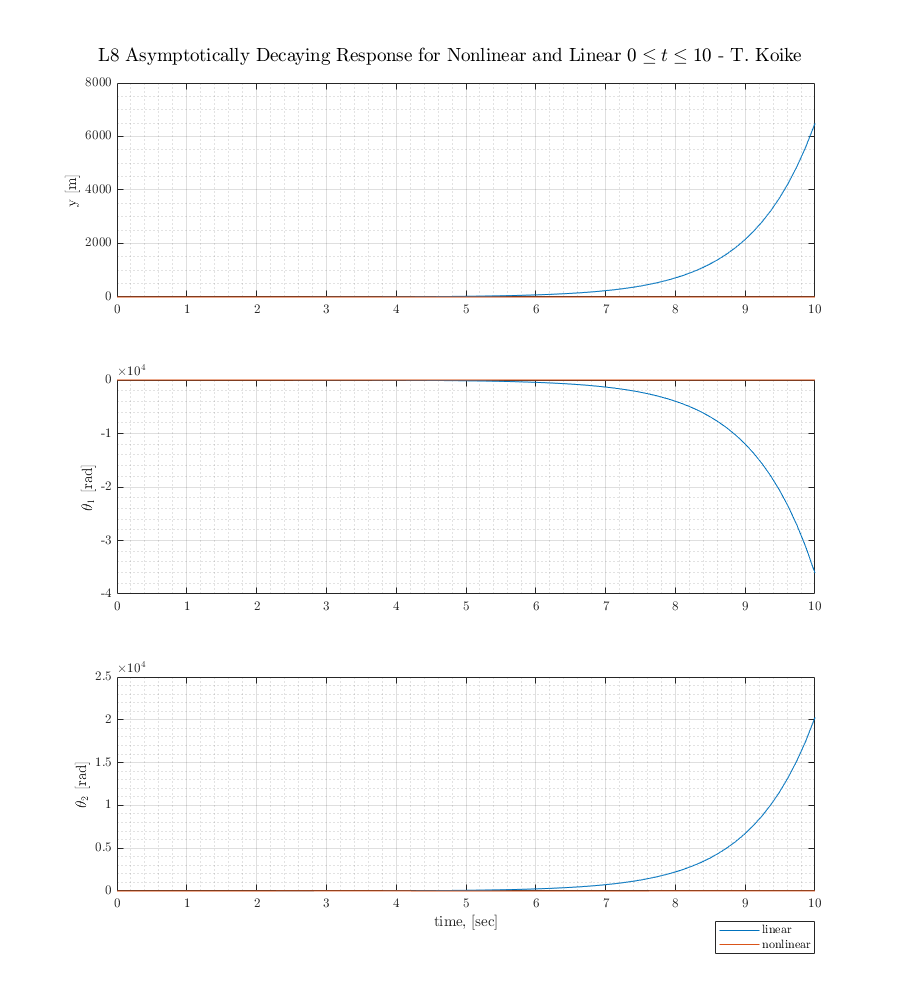

% Plotting 
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
subplot(3,1,1)
hold on; grid on; grid minor; box on;
plot(time1,dy)
plot(time2,y)
ylabel('y [m]')
hold off
subplot(3,1,2)
hold on; grid on; grid minor; box on;
plot(time1,dt1)
plot(time2,t1)
ylabel('$\theta_1$ [rad]')
hold off
subplot(3,1,3)
hold on; grid on; grid minor; box on;
plot(time1,dt2)
plot(time2,t2)
ylabel('$\theta_2$ [rad]')
xlabel('time, [sec]')
h = legend('linear','nonlinear'); set(h, 'Position',  [0.8, 0.05, .1, .025]);
hold off
sgtitle('L8 Asymptotically Decaying Response for Nonlinear and Linear $0\leq t \leq 10$ - T. Koike')
saveas(fig1, 'p9_c_v2.png')

function define_params(L)
    % Function to define parameters
    global m l g ye t1e t2e
    if L == "L1"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; t1e = 0; t2e = 0; % E1
    elseif L == "L2"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; t1e = pi; t2e = pi; % E2 
    elseif L == "L3"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; t1e = 0; t2e = 0; % E1
    elseif L == "L4"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; t1e = pi; t2e = pi; % E2 
    elseif L == "L5"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; t1e = 0; t2e = 0; % E1
    elseif L == "L6"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; t1e = pi; t2e = pi; % E2 
    elseif L == "L7"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; t1e = 0; t2e = 0; % E1
    elseif L == "L8"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; t1e = pi; t2e = pi; % E2
    else
        print('error: did not match any')
    end
end